# Intertemporal Income and Substitution Effects

**Back to **[**Intro Math for Econ**](https://math4econ.github.io/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

We solved previously the [Marshallian Utility Maximization Problem](https://math4econ.github.io/opti_hh_constrained_brsv/household_c1_c2_constrained.html) and the [Hicksian Expenditure Minimization Problem](https://math4econ.github.io/opti_hh_constrained_brsv/household_c1_c2_constrained_expmin.html), now we solve for the effect of a change in price (relative price) on optimal choices. We decompose the effects to two ingredients, the income and substitution effects. This is the Slutsky Decomposition. The key point here is that when price changes, that has changes both the relative costs but also changes income directly and indirectly.

## Utility Maximization over Consumption in Two Periods

We solved the [constrained utility maximization probem](https://math4econ.github.io/opti_hh_constrained_brsv/household_c1_c2_constrained.html) already. 

- **Utility**: $U(c_{1}, c_{2}) = \log(c_{1}) + \beta \cdot \log(c_{2})$

- **Budget Today and Tomorrow Together**: $c_{1}\cdot(1 + r) + c_{2} = Z_1 \cdot (1+r) + Z_2$

## Solving for the Substitution Effect

There are different definitions of the substitution effect. One way of thinking about it is that given that the change in $r$, what would the consumption bundle be at the new prices that would give the household the same level of utility as before. To find this point, we can solve for the household's [Hicksian Expenditure Minimization Problem](https://math4econ.github.io/opti_hh_constrained_brsv/household_c1_c2_constrained_expmin.html). But unlike before, we have to worry about two different prices, in our case two different interest rates. Our objective function uses the second interest rate, the new interest rate that we have shifted to. But the targeted utility level we are trying to achieve is based on the previous, existing interest rate. 

Specifically, the difference between the solution to the problem below and the optimal choices from the Marshallian problem given the initial prices $r_1$ represents the substitution effect. The difference betwen the solution to the problem below and the Marshallian problem given the new prices $r_2$ represent the income effects:

- **Expenditure** we want to **minimize** given **new** price $r_2$: 


$$\min_{c1, c2} \left( c_2 + (1+r_2) c_1 \right)$$


The constraint is however, a function or $r_1$, where $r_1$ determines the $V^*$, we are shifting to some point along the blue dashed line:

- **Constraint** we need to satisfy given **Indirect Utility** with **old** price $r_1$: 


$$\log(c_1) + \beta \log(c_2) = V^*(r_1)$$


The problem here is solves in terms of consumption in two periods, we can relabel consumptions in the first and second periods as consumption of Apples and Bananas in the same period. The solution method is the same. Our first order conditions are the same as when we did the [Hicksian Expenditure Minimization Problem](https://math4econ.github.io/opti_hh_constrained_brsv/household_c1_c2_constrained_expmin.html) problem. The only difference is what the $V^{\ast}$ is based on. Following our algebra before, the optimal choice from this problem above is:


$$c^{\ast, \text{substitution}}_{2} = \exp\left( \left(V^{\ast}(r_1, Z_1, Z_2) + \log(\beta\cdot(1+r_2)) \right) \cdot \frac{1}{1+\beta}\right)$$


Then we can find the $c_1^{\ast}$ choice as well. Below we show the results graphically

## Optimal Consumption Choices with Different Interest Rates

In the following sections, we show the substitution and income effects graphically. First, we already solved the [constrained utility maximization probem](https://math4econ.github.io/opti_hh_constrained_brsv/household_c1_c2_constrained.html) already, and derived the analytical solutions. Below, we solve for the numerical values directly using matlab. We could have also used our analytical solutions, and plugged in values. Sometimes, if it is possible for matlab to analytically solve an equation for you, it is perhaps better to rely on matlab to take derivatives and solve. This way, we reduce potential errors in our algebraic derivations. We often do like to derive the solution analytically by hand as we did in [constrained utility maximization probem](https://math4econ.github.io/opti_hh_constrained_brsv/household_c1_c2_constrained.html) to gain more insights about how parameters impact optimal choices. 

Below is our numerical solutions based on matlab's analytical solution combined with numerical values. We provide two interest rates below, and graphically show the optimal consumption choices with corresponding budgets and indifference curves at for each interest rate.

beta = 0.90;
z1 = 0.5;
z2 = 2.5;
syms r c1 c2 mu
% The Lagrangian
lagrangian = (log(c1) + beta*log(c2)) - mu*( c2 + (1+r)*c1 - z1*(1+r) - z2);
% Given we have many symbols, type K, L, mu at the end to let matlab know what we are solving for
solu = solve(diff(lagrangian, c1)==0, diff(lagrangian, c2)==0, diff(lagrangian, mu)==0, c1, c2, mu, 'Real', true);
solu_c1 = (solu.c1);
solu_c2 = (solu.c2);

At two different interest rate levels, the optimal choices and utility at optimal choices are of course different, we can plot both out graphically following what we did [before](https://math4econ.github.io/optimization_application/household_c1_c2_constrained.html). Note that changing $r$ directly changes both left hand side and right hand side of budget. If we were considering just apples and bananas, unless you sell apples or bananas, the price change would only impact the left-hand-side of the budget (which still lead to both income and substitution effects).

% Get Optimal Choices and Utility at Optimal Choices
syms c1
r1 = 0.05;
r2 = 1;
c1star_r1 = double(subs(solu_c1, {r}, {r1}));
c1star_r2 = double(subs(solu_c1, {r}, {r2}));
c2star_r1 = double(subs(solu_c2, {r}, {r1}));
c2star_r2 = double(subs(solu_c2, {r}, {r2}));
disp(table(c1star_r1, c1star_r2, c2star_r1, c2star_r2));

    c1star_r1    c1star_r2    c2star_r1    c2star_r2
    _________    _________    _________    _________

     1.5163       0.92105      1.4329       1.6579  



U_at_c_opti_r1 = log(c1star_r1) + beta*log(c2star_r1)

U_at_c_opti_r1 = 0.7400

U_at_c_opti_r2 = log(c1star_r2) + beta*log(c2star_r2)

U_at_c_opti_r2 = 0.3728

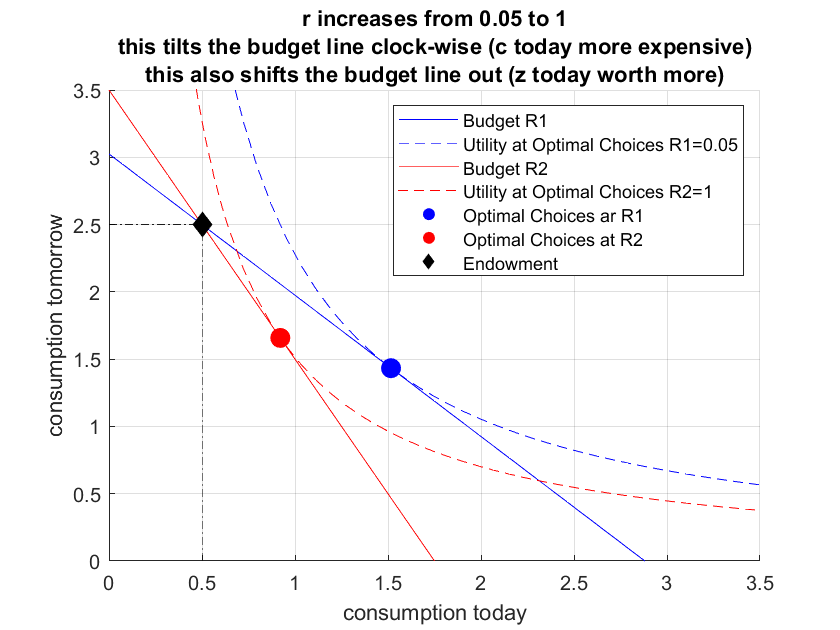


% The Budget Line at r1
f_budget_r1 = z1*(1+r1) + z2 - (1+r1)*c1;
% Indifference at V* at r1
f_indiff_r1 = exp((U_at_c_opti_r1-log(c1))/(beta));

% The Budget Line at r2
f_budget_r2 = z1*(1+r2) + z2 - (1+r2)*c1;
% Indifference at V* at r2
f_indiff_r2 = exp((U_at_c_opti_r2-log(c1))/(beta));

% Graph
figure();
hold on;
% r1
fplot(f_budget_r1, [0, (z1 + z2/(1+r2))*2], 'b');
fplot(f_indiff_r1, [0, (z1 + z2/(1+r2))*2], 'b--');
% r2
fplot(f_budget_r2, [0, (z1 + z2/(1+r2))*2], 'r');
fplot(f_indiff_r2, [0, (z1 + z2/(1+r2))*2], 'r--');
% optmial points
scatter(c1star_r1, c2star_r1, 100, 'b', 'filled');
scatter(c1star_r2, c2star_r2, 100, 'r', 'filled');
% Endowment Point
scatter(z1, z2, 100, 'k', 'filled', 'd');
plot(linspace(0,z1,10),ones(10,1) * z2, 'k-.', 'HandleVisibility','off');
plot(ones(10,1) * z1, linspace(0,z2,10), 'k-.', 'HandleVisibility','off');
% legends
ylim([0, (z1 + z2/(1+r2))*2])
xlabel('consumption today');
ylabel('consumption tomorrow');
legend({'Budget R1', ['Utility at Optimal Choices R1=' num2str(r1)],...
        'Budget R2', ['Utility at Optimal Choices R2=' num2str(r2)],...
        'Optimal Choices ar R1', 'Optimal Choices at R2', 'Endowment'})
title({['r increases from ' num2str(r1) ' to ' num2str(r2)],...
       ['this tilts the budget line clock-wise (c today more expensive)'],...
       ['this also shifts the budget line out (z today worth more)']}) 
grid on;

## Graphical Illustration of the Income and Substitution Effect

Based on our solution method above, we can solve for the substitution effects and income effects. The solid red dot below is the new point we added based on the minimization problem earlier.

syms c1 c2 lambda
% The Lagrangian given U_at_c_opti found earlier
lagrangian = (c2 + (1+r2)*c1 - lambda*( log(c1) + beta*log(c2) - U_at_c_opti_r1));
% Solve
solu_min_substitution = solve(diff(lagrangian, c1)==0, diff(lagrangian, c2)==0, diff(lagrangian, lambda)==0, c1, c2, lambda, 'Real', true);
solu_min_substitution_c1 = double(solu_min_substitution.c1);
solu_min_substitution_c2 = double(solu_min_substitution.c2);
total_cost = solu_min_substitution_c2 + (1+r2)*solu_min_substitution_c1;
disp(table(solu_min_substitution_c1, solu_min_substitution_c2, total_cost));

    solu_min_substitution_c1    solu_min_substitution_c2    total_cost
    ________________________    ________________________    __________

             1.1174                      2.0114               4.2463  



We have found the bundle along the dashed blue line where the tangent line to the dashed blue line has the same slope as the solid red line. We can now graph this out:

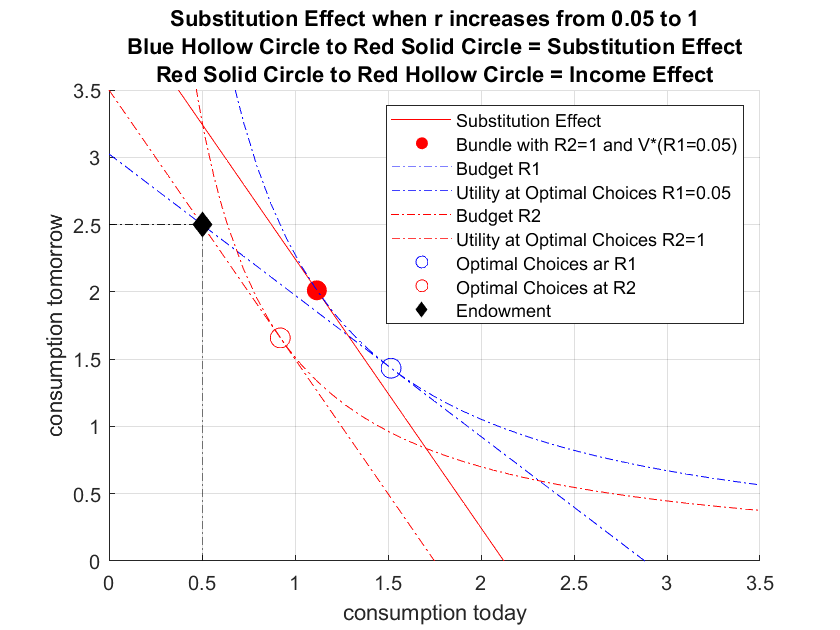

% Same as before: The Budget Line at r1
f_budget_r1 = z1*(1+r1) + z2 - (1+r1)*c1;
% Same as before: Indifference at V* at r1
f_indiff_r1 = exp((U_at_c_opti_r1-log(c1))/(beta));

% Rather than plugging in z1*(1+r2) + z2, now we are pushing the red budget line out
% z1_substi*(1+r2) + z2_substi = solu_min_substitution_c2 + (1+r2)*solu_min_substitution_c1
f_budget_substitution = total_cost - (1+r2)*c1;

% Graph
figure();
hold on;
% Substitution Effect
fplot(f_budget_substitution, [0, (z1 + z2/(1+r2))*2], 'r');
scatter(solu_min_substitution_c1, solu_min_substitution_c2, 100, 'r', 'filled');
% r1
fplot(f_indiff_r1, [0, (z1 + z2/(1+r2))*2], 'b-.');
fplot(f_budget_r1, [0, (z1 + z2/(1+r2))*2], 'b-.');
fplot(f_budget_r2, [0, (z1 + z2/(1+r2))*2], 'r-.');
fplot(f_indiff_r2, [0, (z1 + z2/(1+r2))*2], 'r-.');
% legends
ylim([0, (z1 + z2/(1+r2))*2])
% optmial points
scatter(c1star_r1, c2star_r1, 100, 'b');
scatter(c1star_r2, c2star_r2, 100, 'r');
% Endowment Point
scatter(z1, z2, 100, 'k', 'filled', 'd');
plot(linspace(0,z1,10),ones(10,1) * z2, 'k-.', 'HandleVisibility','off');
plot(ones(10,1) * z1, linspace(0,z2,10), 'k-.', 'HandleVisibility','off');
% legends
ylim([0, (z1 + z2/(1+r2))*2])
xlabel('consumption today');
ylabel('consumption tomorrow');
legend({'Substitution Effect', ['Bundle with R2=' num2str(r2) ' and V*(R1=' num2str(r1) ')'] ...
        'Budget R1', ['Utility at Optimal Choices R1=' num2str(r1)],...
        'Budget R2', ['Utility at Optimal Choices R2=' num2str(r2)],...
        'Optimal Choices ar R1', 'Optimal Choices at R2', 'Endowment'})
title({['Substitution Effect when r increases from ' num2str(r1) ' to ' num2str(r2)]...
       ['Blue Hollow Circle to Red Solid Circle = Substitution Effect']...
       ['Red Solid Circle to Red Hollow Circle = Income Effect']});
grid on;

In the graph above, the shift between the empty blue circle and the red solid circle is the substitution effect. Remaining changes between empty blue circle and red blue circle are due to income effects. Note that in this problem, the substitution effect--given higher interest rate for a household that would like to borrow due to low endowment today--is to reduce consumption today and increasing consumption tomorrow. The income effect, however, is moving both consumption today and tomorrow down. 

It might be puzzling whey the income effect is shifting both $c_1$ and $c_2$ lower. This is because even though the higher interest rate increases the right hand side of the budget constraint, that increase in income is small relative to the effective loss in income due to the dramatically higher cost of borrowing. In another word, the dollar level of the household is higher due to higher interest rate, but the purchasing power of that wealth is significantly lower due to higher interest rate, so the higher dollar level is actually worth less in consumption units. There is a decrease in the household's ability to purchase consumption in both periods given the increase in interest rate. Given that the household was borrowing before (notice where the endowment point is), the household is hurt by the increase in interest rate. The household now still borrows, but borrows less. 

This type of problem works in the Apples and Bananas case as well. Suppose you have endowments in Apples and Bananas, when the price of apple increases, your wealth directly increases from selling your apples endowments at higher prices, but you also have to pay higher cost when you buy apple which leads to an indirect income effect and substitution effect. In general, when our endowments are in terms of goods, changing price tilts the budget constraint but the constraint still has to pass through the black endowment point. If we have just some total endowment in cash, and not in goods, meaning our endowments are not related to prices, then our budget line, given price change would tilt at the y and x intercepts.